load C:\class\coursefiles\mlbe\exercises\cassiniData2.mat

Date = data(1,:);
Year = data(:,1);
Month = data(:,2);
Day = data(:,3);

X = data(:,4);
Y = data(:,5);
Z = data(:,6);

Radius = sqrt(X.^2 + Y.^2 + Z.^2);

orbits = table(0.39, 0.72, 1.0, 1.51, 5.0, 9.04, 19.18, 30.06);
orbits.Properties.VariableNames = {'Mercury','Venus','Earth',...
    'Mars','Jupiter','Saturn','Uranus','Neptune'};

z = orbits(1,[1 2 3 4 5 6 7 8]);


## Mercury

passMercury = Radius >= orbits.Mercury;
datePassMerc = data(passMercury,:);
x = datePassMerc(:,4);
y = datePassMerc(:,5);


%plot(x,y);
%hold on


## Matt's Soln

Planets = {'Mercery','Venus','Earth','Mars',...
    'Jupiter','Saturn','Uranus','Neptune'};
OrbitRad = [0.39, 0.72, 1.0, 1.51, 5.0, 9.04, 19.18, 30.06];

Radial = sqrt(X.^2 + Y.^2 + Z.^2);

for i = 1 : 8
vidx = Radial == OrbitRad(i);
nnz(vidx);
Planets(i)
vTime = [Year(vidx), Month(vidx), Day(vidx)];
end

ans =     'Mercery'


ans =     'Venus'


ans =     'Earth'


ans =     'Mars'


ans =     'Jupiter'


ans =     'Saturn'


ans =     'Uranus'


ans =     'Neptune'



min(Year)

ans = 1997

max(Year)

ans = 2004

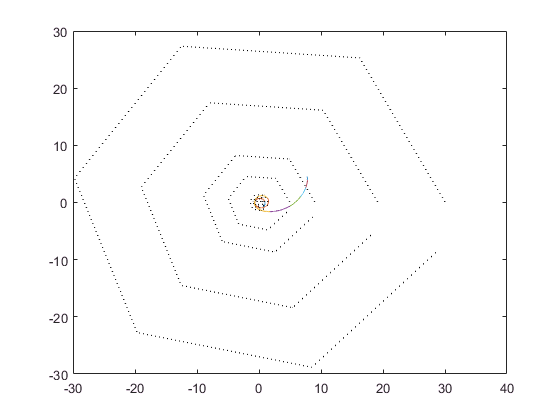


for j = 1997 : 2004
idx = Year == j;
plot(X(idx),Y(idx));
hold on
end

ang = [0:2*pi];

xp = OrbitRad.*cos(ang');
yp = OrbitRad.*sin(ang');

plot(xp,yp,'k:')